trainTow=importTowFile('train_TowM.csv');
testTow=importTowFile('test_TowM.csv');

Ypredict=trainedModelbagged.predictFcn(testTow);

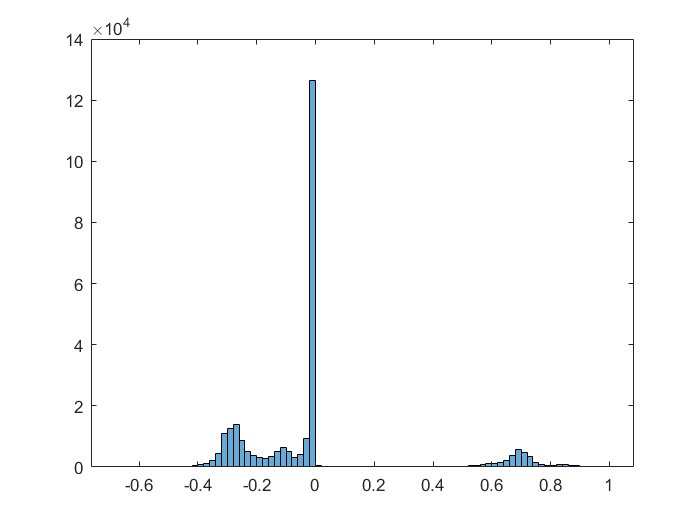

yPredict1=trainedModelbagged.predictFcn(trainTow);

yActual=trainTow.accepted;
residual=yActual-yPredict1;
histogram(residual)

TowPredict=array2table(testTow.id);

TowPredict.accepted=Ypredict;



for c=1:height
    if TowPredict.accepted(c)>0.2
       TowPredict.accepted(c)=1; 
    else 
        TowPredict.accepted(c)=0;
    end
end

groupsummary(TowPredict,'accepted')

ans = 2×2 table
    accepted    GroupCount
    ________    __________

       0          74184   
       1          40149   


writetable(TowPredict,"TowPredict5.csv");